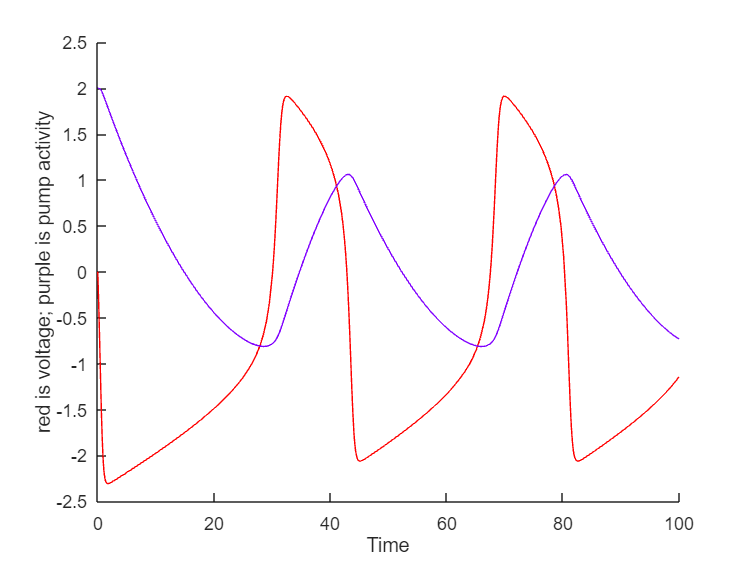

c = 0.08;
a = 0.5;
b = 0.2;
v=@(v,w) v-(1/3)*v^3-w;
w=@(v,w) c*(v+a-b*w);
dxdt = @(t,x)[v(x(1),x(2));
              w(x(1),x(2))];

[T, X] = ode45(@(t,x)[v(x(1),x(2));w(x(1),x(2))], [0,100], [0.0,2.0] );

figure; hold on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('red is voltage; purple is pump activity')
xlabel('Time')

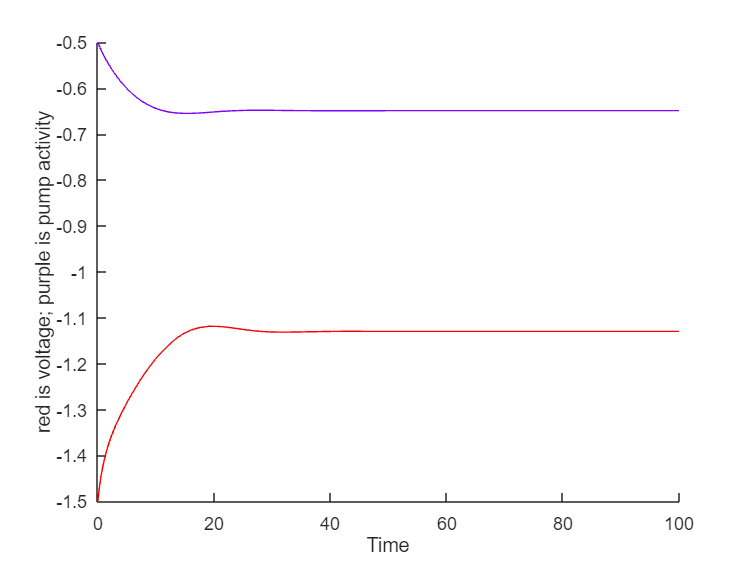

c = 0.08;
a = 1.0;
b = 0.2;
v=@(v,w) v-(1/3)*v^3-w;
w=@(v,w) c*(v+a-b*w);
dxdt = @(t,x)[v(x(1),x(2));
              w(x(1),x(2))];

[T, X] = ode45(@(t,x)[v(x(1),x(2));w(x(1),x(2))], [0,100], [-1.5,-0.5] );

figure; hold on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('red is voltage; purple is pump activity')
xlabel('Time')

display(X(65,1));

   -1.1298



display(X(65,2));

   -0.6491



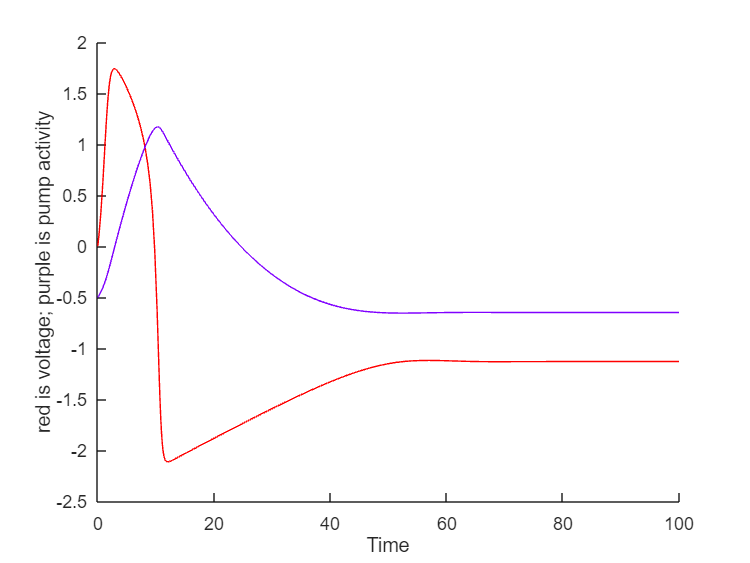

c = 0.08;
a = 1.0;
b = 0.2;
v=@(v,w) v-(1/3)*v^3-w;
w=@(v,w) c*(v+a-b*w);
dxdt = @(t,x)[v(x(1),x(2));
              w(x(1),x(2))];

[T, X] = ode45(@(t,x)[v(x(1),x(2));w(x(1),x(2))], [0,100], [-0.0,-0.5] );

figure; hold on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('red is voltage; purple is pump activity')
xlabel('Time')

display(X(65,1));

   -1.5139



display(X(65,2));

    1.1579



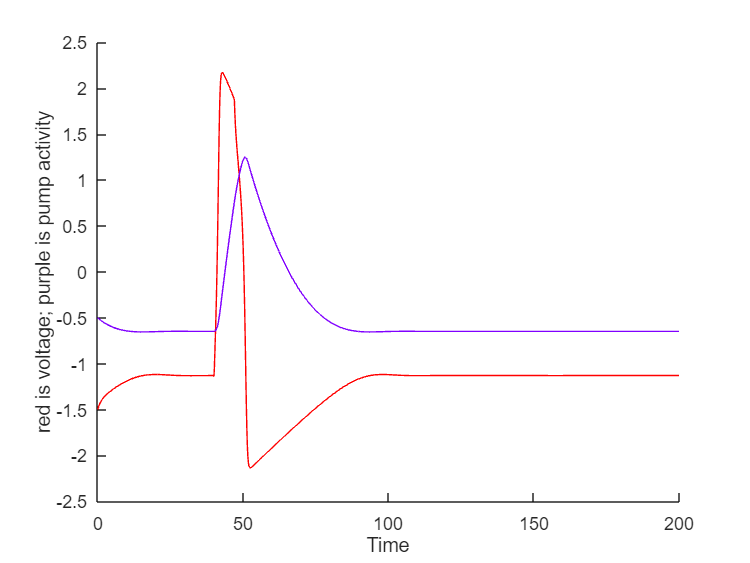

I0 = 1.0;
tStart = 40;
tStop = 47;
c = 0.08;
a = 1.0;
b = 0.2;
I=@(t) I0*(t>tStart).*(t<tStop);
v=@(v,w,t) v-(1/3)*v^3-w+I(t);
w=@(v,w,t) c*(v+a-b*w);
dxdt = @(t,x)[v(x(1),x(2),t);
              w(x(1),x(2),t)];

[T, X] = ode45(@(T,X)[v(X(1),X(2),T);w(X(1),X(2),T)], [0,200], [-1.5,-0.5] );

figure; hold on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('red is voltage; purple is pump activity')
xlabel('Time')

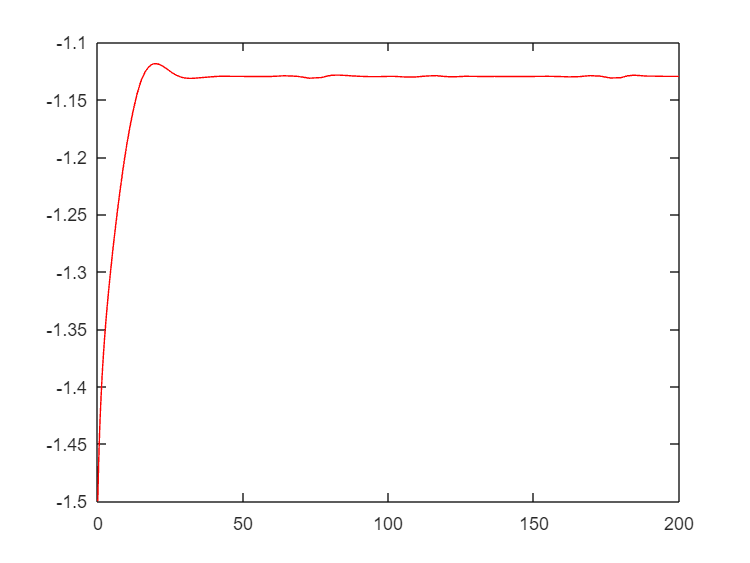

D= 0.9;
c = 0.08;
a = 1.0;
b = 0.2;
v1=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v1-(1/3)*v1^3-w1+D*(v10-2*v1+v2);
w1=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v1+a-b*w1);

v2=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v2-(1/3)*v2^3-w2+D*(v1- 2*v2 + v3);
w2=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v2+a-b*w2);

v3=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v3-(1/3)*v3^3-w3+D*(v2 - 2*v3 + v4);
w3=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v3+a-b*w3);

v4=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v4-(1/3)*v4^3-w4+D*(v3 - 2*v4 + v5);
w4=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v4+a-b*w4);

v5=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v5-(1/3)*v5^3-w5+D*(v4 - 2*v5 + v6);
w5=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v5+a-b*w5);

v6=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v6-(1/3)*v6^3-w6+D*(v5- 2*v6 + v7);
w6=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v6+a-b*w6);

v7=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v7-(1/3)*v7^3-w7+D*(v6 - 2*v7 + v8);
w7=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v7+a-b*w7);

v8=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v8-(1/3)*v8^3-w8+D*(v7 - 2*v8 + v9);
w8=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v8+a-b*w8);

v9=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v9-(1/3)*v9^3-w9+D*(v8 - 2*v9 + v10);
w9=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v9+a-b*w9);

v10=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v10-(1/3)*v10^3-w10+D*(v9 - 2*v10 + v1);
w10=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v10+a-b*w10);

dxdt = @(t,x)[
    v1(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v3(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v4(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v5(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v6(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v7(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v8(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v9(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    v10(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w1(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w3(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w4(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w5(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w6(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w7(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w8(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w9(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20));
    w10(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20))];

[T, X] = ode45(@(T,X)[v1(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v2(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v3(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v4(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v5(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v6(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v7(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v8(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v9(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v10(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w1(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w2(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w3(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w4(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w5(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w6(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w7(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w8(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w9(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w10(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20))], [0,200], [-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,] );

figure;
plot(T,X(:,1),'-r'); % red for RNA

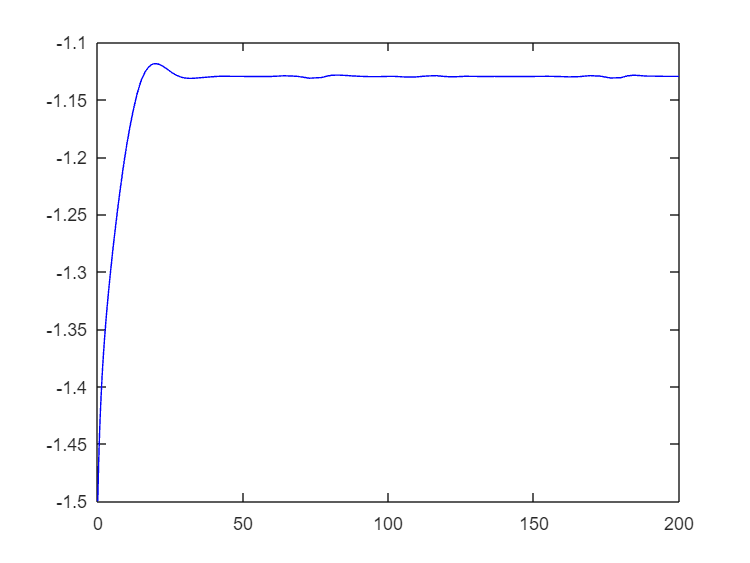

figure; 
plot(T,X(:,2),'-b')

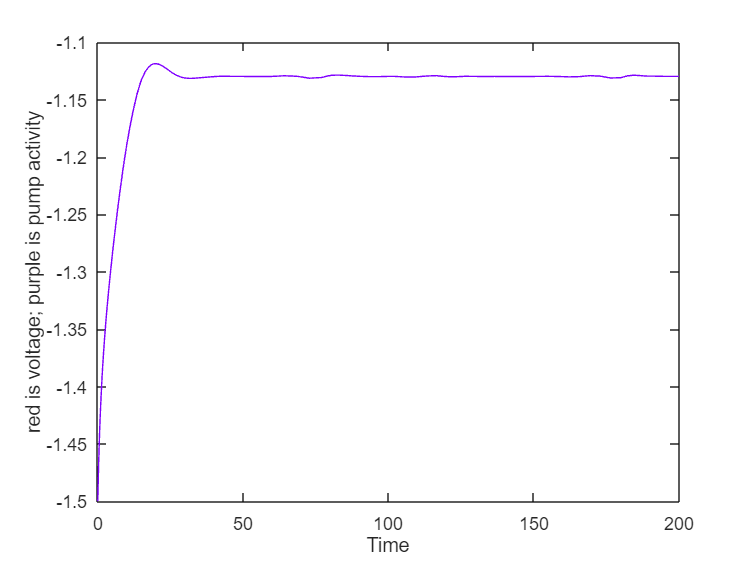

figure;
plot(T,X(:,3),'-', 'color', [0.5 0 1]); % purple for protein
ylabel('red is voltage; purple is pump activity');
xlabel('Time');

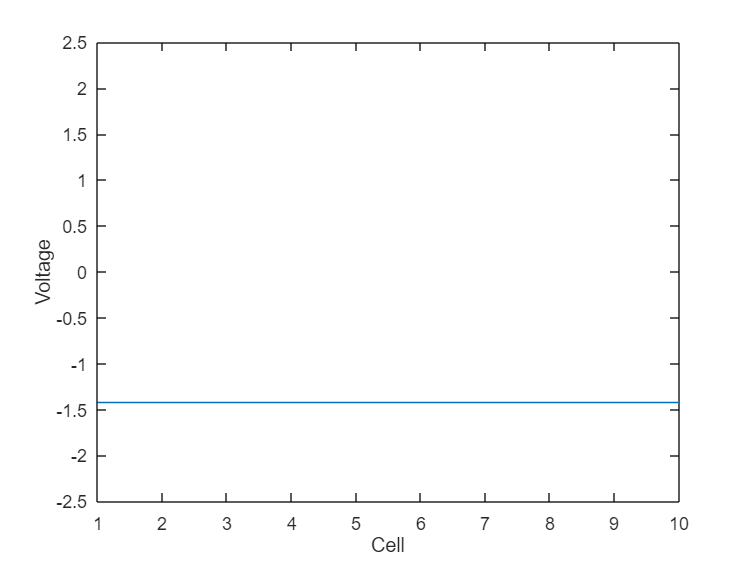


for nt=1:numel(T)
figure(5); clf; hold on; box on;
plot(X(nt,1:10));
set(gca,'ylim', [-2.5,2.5])
xlabel('Cell');
ylabel('Voltage')
drawnow;
end

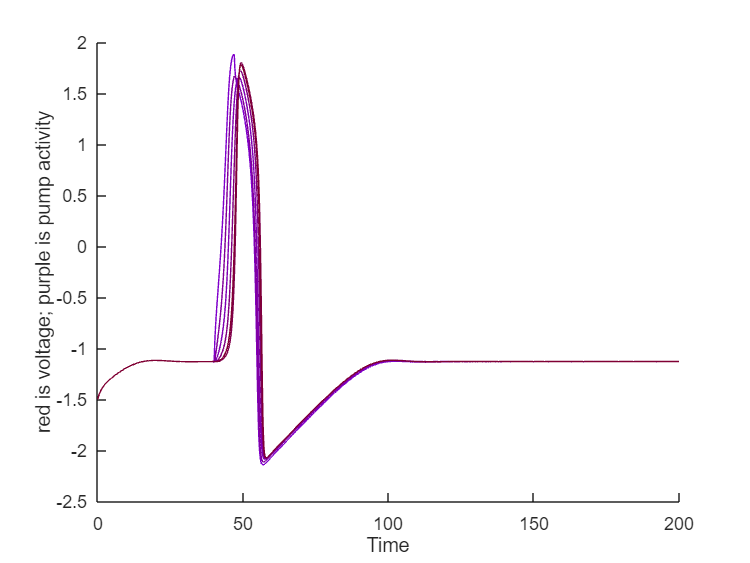

I0 = 1.0;
tStart = 40;
tStop = 47;
I=@(t) I0*(t>tStart).*(t<tStop);
v1=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v1-(1/3)*v1^3-w1+D*(v10-2*v1+v2);
w1=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v1+a-b*w1);

v2=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v2-(1/3)*v2^3-w2+D*(v1- 2*v2 + v3);
w2=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v2+a-b*w2);

v3=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v3-(1/3)*v3^3-w3+D*(v2 - 2*v3 + v4);
w3=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v3+a-b*w3);

v4=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10,t) v4-(1/3)*v4^3-w4+D*(v3 - 2*v4 + v5)+I(t);
w4=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v4+a-b*w4);

v5=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v5-(1/3)*v5^3-w5+D*(v4 - 2*v5 + v6);
w5=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v5+a-b*w5);

v6=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v6-(1/3)*v6^3-w6+D*(v5- 2*v6 + v7);
w6=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v6+a-b*w6);

v7=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v7-(1/3)*v7^3-w7+D*(v6 - 2*v7 + v8);
w7=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v7+a-b*w7);

v8=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v8-(1/3)*v8^3-w8+D*(v7 - 2*v8 + v9);
w8=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v8+a-b*w8);

v9=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v9-(1/3)*v9^3-w9+D*(v8 - 2*v9 + v10);
w9=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v9+a-b*w9);

v10=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) v10-(1/3)*v10^3-w10+D*(v9 - 2*v10 + v1);
w10=@(v1,v2,v3,v4,v5,v6,v7,v8,v9,v10, ...
    w1,w2,w3,w4,w5,w6,w7,w8,w9,w10) c*(v10+a-b*w10);

dxdt = @(t,x)[
    v1(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v3(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v4(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v5(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v6(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v7(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v8(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v9(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    v10(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w1(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w3(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w4(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w5(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w6(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w7(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w8(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w9(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t);
    w10(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18),x(19),x(20),t)];

[T, X] = ode45(@(T,X)[v1(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v2(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v3(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v4(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20),T);
    v5(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v6(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v7(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v8(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v9(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    v10(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w1(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w2(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w3(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w4(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w5(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w6(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w7(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w8(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w9(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20));
    w10(X(1),X(2),X(3),X(4),X(5),X(6),X(7),X(8),X(9),X(10),X(11),X(12),X(13),X(14),X(15),X(16),X(17),X(18),X(19),X(20))], [0,200], [-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-1.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5,-0.5] );

figure;hold on;
plot(T,X(:,1),'-r'); 
plot(T,X(:,2),'-b')
plot(T,X(:,3),'-', 'color', [0.5 0 1]); 
plot(T,X(:,4),'-', 'color', [0.5 0 0.8]);
plot(T,X(:,5), 'color', [0.5 0 0.6]);
plot(T,X(:,6), 'color', [0.5 0 0.7]);
plot(T,X(:,7), 'color', [0.5 0 0.5]);
plot(T,X(:,8), 'color', [0.5 0 0.4]);
plot(T,X(:,9), 'color', [0.5 0 0.3]);
plot(T,X(:,10), 'color', [0.5 0 0.2]);
ylabel('red is voltage; purple is pump activity');
xlabel('Time');